`LIS4042 Artificial Vision `

`Professor Zobeida Guzmán `

`Autumn 2022 UDLAP` 

Efrain Leon Arellano 168417

Aldo Sánchez Gil 167759� 

Hector Zepeda Gonzalez 166896

# Automatic License Plate Recognition Application

The main objective of the code is to make possible the creation of a system which has different stages, one of them was to apply different filters to have an image improvement, main characteristics are extracted, which in this case are the plate with its text and finally the recognition of alphanumeric signs

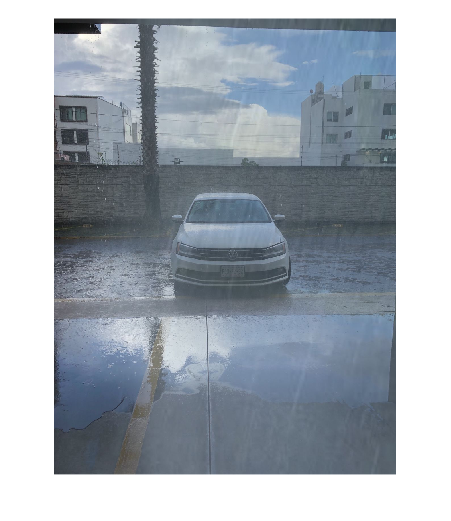

Plate= imread("ALPR3.jpg");% Variable Plate equal to the input Image (Car Image)
imshow(Plate)% Display the image

I= rgb2gray(Plate);%Converts RGB images to grayscale 
 

# Filters Applied

Then it was important to apply some type of enhancement to the image, because different images may contain too many factors that affect the correct appreciation and analysis of the different images. The filters proposed for improvement were the following:

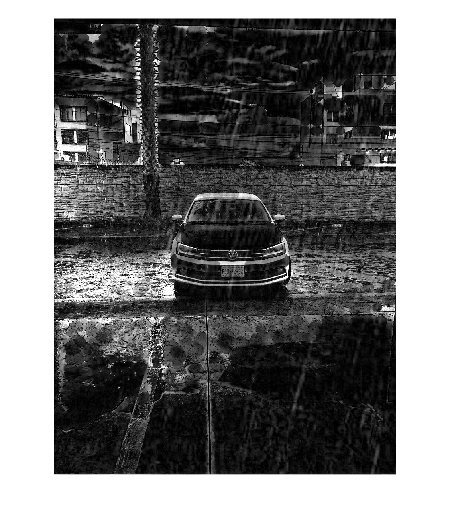

%{
ADAPTHISTEQ= CONTRAST ENHACEMENT----> given a better result of contrast by
transforming the values using CONTRAS-LIMITED ADAPTIVE HISTOGRAM
EQUALIZATION.
%}
contrast_enh = adapthisteq(I); %Applying contrast enhacement to the image and assigned to the variable
%{
Preprocess of the image to make the background more uniform
%}
se = strel('disk',15); %Remove all the foreground using morphological opening. 
% The opening operation removes small objects that cannot 
% completely contain the structuring element (se). 
% Define a disk-shaped ‘se’ with a radius of 15

background = imopen(contrast_enh,se);% Perfoming erosion following by dilatation

nonuf_illu = contrast_enh - background;% Substracting background=UNIFORM BACKGROUND
I3=imadjust(nonuf_illu);% Used imadjust for increase the contrast 
imshow(I3)% Dispay the image

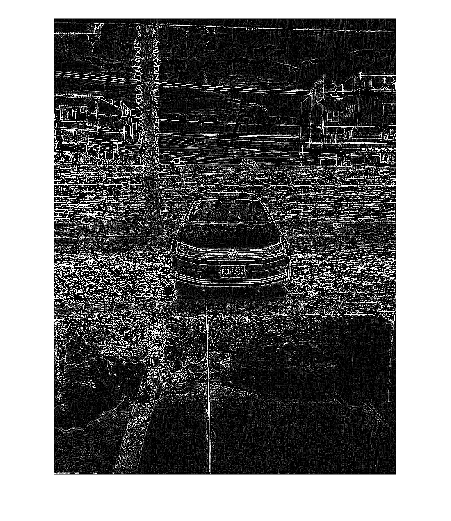

%{ It identifies points in a digital image at which the 
%image brightness changes sharply or has discontinuities
%}
h = fspecial('log',7,0.4);%Returns a rotationally symmetric 
% Gaussian lowpass filter of size hsize with standard deviation sigma
lalacian_Gau=imfilter(I3,h);%Applying the predefined filter to the image
imshow(lalacian_Gau)% Display image

# ROI with specific characeristics 

After having proposed improvements to our image, it was important for us to take into account a specific region, in this case our plate with our alphanumeric text.

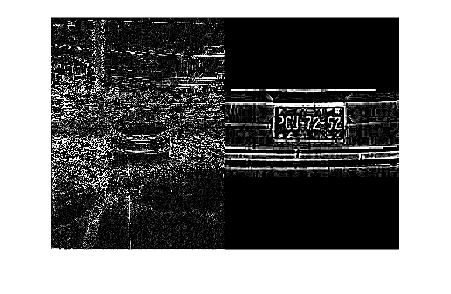

rect = [530 850 200 100]; %Select roi by a region given with the width and height

Img1_roi = lalacian_Gau( rect(2) : (rect(2)+rect(4)) , rect(1) : (rect(1)+rect(3)) , : ); %Store roi in matrix

montage({lalacian_Gau, Img1_roi})% Shows original Image wiht the ROI stablished

# Model CRAFT with the Character recognition using OCR

Finally, a pretrained model was used to make it possible to locate characters within a specific area, through bounding boxes which were passed to our OCR character recognition for the text output.

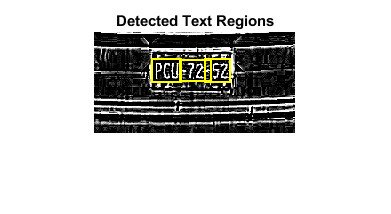

bbox=detectTextCRAFT(Img1_roi,CharacterThreshold=0.3);% Function with image input and character threshold( score for grouping detected texts) 
IoutTH3= insertShape(Img1_roi,"rectangle",bbox,LineWidth=2);%Inserting the rectangle with specific widht

imshow(IoutTH3); %display the detected text regions with bounding boxes
title("Detected Text Regions")


output = ocr(Img1_roi,bbox); %Application of OCR to the image with the BBX
fprintf("RECOGNIZED CHARACTERS: \n");

RECOGNIZED CHARACTERS: 


disp([output(1,1).Words]) %Displaying recognized Characters position (1,1)

    {'PCU'}



disp([output(2,1).Words])%"   "

    {':72‘'}





newBbox=detectTextCRAFT(Img1_roi,CharacterThreshold=0.4);% " "
IoutTH4= insertShape(Img1_roi,"rectangle",newBbox,LineWidth=2);% " "
output = ocr(Img1_roi,newBbox);% "  "
disp([output(3,1).Words])% " "

    {'52'}

